# CS283 Assignment 1

Enmao Diao, 09/15/2017

# Question 1

## 1 (a)

read a image based on its filename and print its height and width in pixels.

% code here
filepath = './data';
filename = 'baboon';
format = 'tif';
full_filename = strcat(filepath,'/',filename,'.',format);
baboon = imread(full_filename);
shape = size(baboon);
fprintf('size of %s.%s is %dx%d',filename,format,shape(1),shape(2));

size of baboon.tif is 512x512

## 1(b) 

grayscale of image and RGB component of this image from left to the right

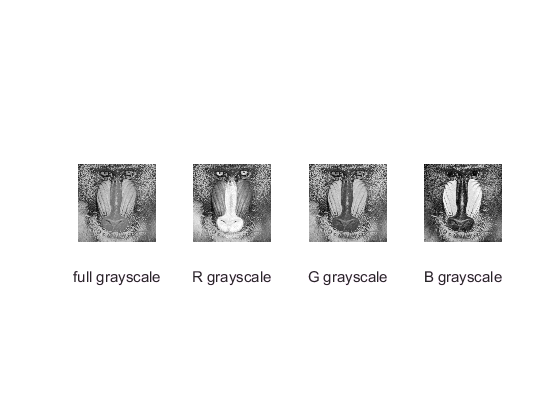

% code here
gray_baboon = rgb2gray(baboon);
figure
subplot(1,4,1)
imshow(gray_baboon)
xlabel('full grayscale')
subplot(1,4,2)
imshow(baboon(:,:,1))
xlabel('R grayscale')
subplot(1,4,3)
imshow(baboon(:,:,2))
xlabel('G grayscale')
subplot(1,4,4)
imshow(baboon(:,:,3))
xlabel('B grayscale')

## 1(c)

write compressed jpg file into directory with quality 95. After load and show the original and compressed image, we can conclude that it is hard to tell the difference between the compressed image and the original one.

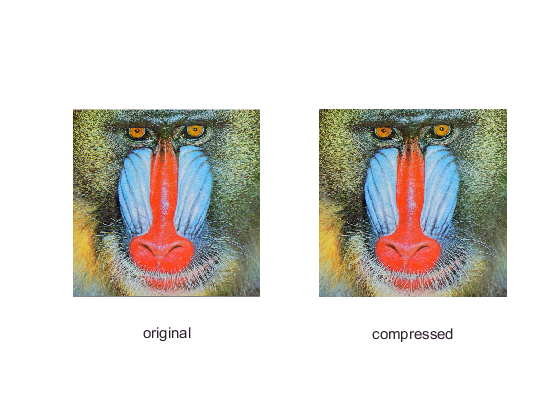

% code here
filename = './data/baboon_compressed.jpg';
quality = 95;
imwrite(baboon,filename,'Quality',quality);
baboon_compressed=imread(filename);
figure
subplot(1,2,1)
imshow(baboon)
xlabel('original')
subplot(1,2,2)
imshow(baboon_compressed)
xlabel('compressed')

## 1(d)

The compression ratio is 774 KB/ 185 KB = 4.1838

## 1(e)

The lowest possible quality is about 40. The compression ratio is 774 KB/ 43.5 KB = 17.7931

# Question 2

## 2 (a)

randomly choose 25% pixels from cameraman and give them values that are uniformly distributed integers within [0,255]

% code here
filename = './data/cameraman.tif';
percent = 0.25

percent = 0.2500

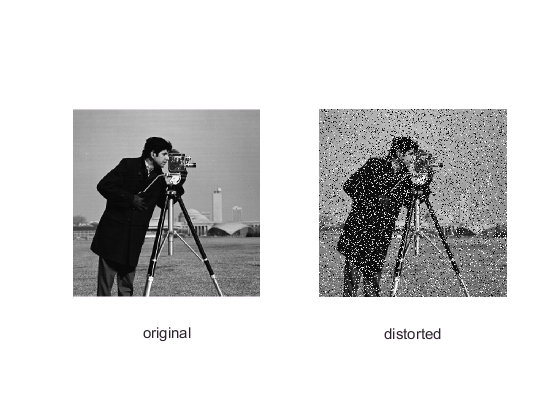

cameraman = imread(filename);
shape = cameraman;
randix = randperm(numel(shape));
partial_randix = randix(1:round(length(randix)*percent+1));
new_cameraman = cameraman;
new_cameraman(partial_randix) = round(rand(1,length(partial_randix))*255);
figure
subplot(1,2,1)
imshow(cameraman)
xlabel('original')
subplot(1,2,2)
imshow(new_cameraman)
xlabel('distorted')

## 2 (b)

At 25%, the picture is recognizable, since we can still identify it shows a cameraman.  By trying different percentage, we can see that the picture is gradually degraded when we assign more random values. The randomly chosen values are usually distinct from their original values and thus quite obvious on the distored pcitures.A slight increase in percentatge can make those points more dense in the picture. At about 80%, the picture is totally unrecognizable, and this process happens gradually from 50% to 80%.

# Question 3

## 3 (a) 


$$argmin  (\mathbf{Ax}- \mathbf{b})^T(\mathbf{Ax}- \mathbf{b}) \\ =  (\mathbf{Ax})^T(\mathbf{Ax}) - \mathbf{b}^T(\mathbf{Ax}) - (\mathbf{Ax})^T\mathbf{b} + \mathbf{b}^T\mathbf{b} \\
=(\mathbf{Ax})^T(\mathbf{Ax}) -2 (\mathbf{Ax})^T\mathbf{b} + \mathbf{b}^T\mathbf{b}$$


take the derivative with respect to $\mathbf X$ and set it equal to zero we have:


$$-2\mathbf{A}^T\mathbf{b} + 2\mathbf{A}^T\mathbf{A}\mathbf{x} = 0\\
\mathbf{A}^T\mathbf{A}\mathbf{x} = \mathbf{A}^T\mathbf{b}\\
\mathbf{x}^* = (\mathbf{A}^T\mathbf{A})^{-1} \mathbf{A}^T\mathbf{b}$$


The result $\mathbf{Ax}^*$ is the projection of vector $\mathbf{b}$ on the column space of $\mathbf{A}$ and the error vector $\mathbf{b}-\mathbf{Ax}$ is orthogonal to the column space

This does not make sense when fitting a line in the image. We normally use homogeneous coordinates to represent lines and plane in a image because we need to preserve some useful properties like colinearity and parallelism. Points look close in $\mathbf{R^2}$ may not have the same distance with respect to the fitted line in $\mathbf{P^2}$.

## 3 (b) 

One way to avoid trivial solution is to add a reasonable constraint, for example $||\mathbf{x}|| = 1$

We can solve this problem with SVD.


$$argmin ||\mathbf{Ax}||_2\text{ , s.t. } ||\mathbf{x}||=1\\
||\mathbf{Ax}|| = ||\mathbf{UDV}^T\mathbf{x}||$$


since $\mathbf{U}$and $\mathbf{V}$are orthogonal matrices $||\mathbf{Ux}|| = ||\mathbf{x}||$, $||\mathbf{V}^T\mathbf{x}||$ = $||\mathbf{x}||$


$$=||\mathbf{DV}^T\mathbf{x}||\\
\mathbf{y} = \mathbf{V}^T\mathbf{x}\\
=||\mathbf{Dy}||
$$


Then it suffices to compute

 
$$argmin ||\mathbf{Dy}||,\text{ , s.t. } ||\mathbf{y}||=1\\ $$


Since $\mathbf{D}$ is diagonal and the elements are sorted descendently. Thus, it is clear that $\mathbf y = [0,0,...,1]^T$

Then, $\mathbf x^*
$ is the last column of $\mathbf{V}$

$\mathbf{Ax}^*$ lies in the null space of $\mathbf{A}$ and $\mathbf{x}^*$ passes through origin

This approach is more useful than (a) in Computer Vision because  we usually use projective space rather than euclidean space. we can also use similar approach to fit conics or some other shapes that can be determined by homogeneous coordinates

## 3 (c)

find indices of red, green, and blue dots, and then use ind2sub to get the coordinates of those dots. Use SVD on the matrix A with coordinates in the first two columns and last column as 1. Extract the optimal $\mathbf x^*$ from the last column of $\mathbf{V}$. Use x coordinates [1 (width of image)] to compute its y coordinates. Finally superimpose fitted line on the image.

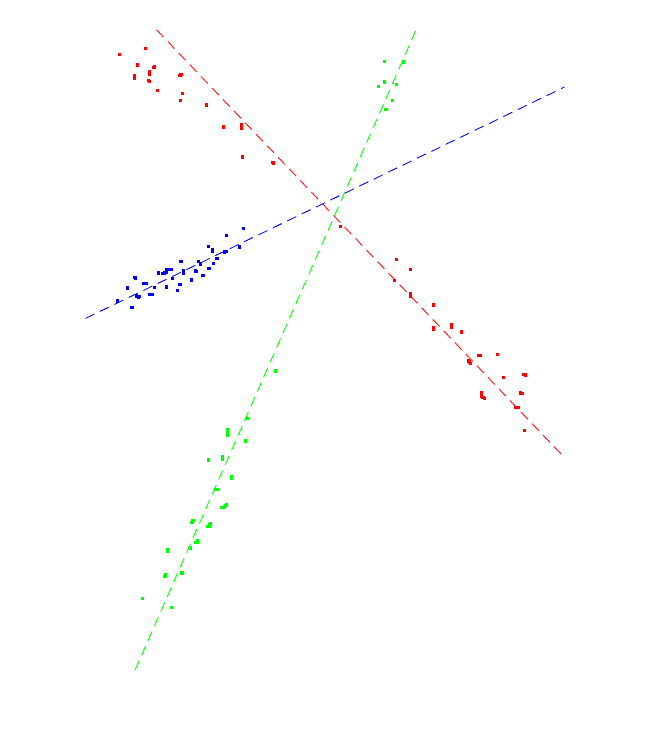

filename = './data/dots.tif';
dots = imread(filename);
shape = size(dots);
redidx = find(dots(:,:,1) == 255 & dots(:,:,2) == 0 & dots(:,:,3) == 0);
greenidx = find(dots(:,:,1) == 0 & dots(:,:,2) == 255 & dots(:,:,3) == 0);
blueidx = find(dots(:,:,1) == 0 & dots(:,:,2) == 0 & dots(:,:,3) == 255);
red_crd = ones(length(redidx),3);
green_crd = ones(length(greenidx),3);
blue_crd = ones(length(blueidx),3);
[red_crd(:,2),red_crd(:,1)] = ind2sub(shape(1:2),redidx); % red coordinates
[green_crd(:,2),green_crd(:,1)] = ind2sub(shape(1:2),greenidx); % green coordinates
[blue_crd(:,2),blue_crd(:,1)] = ind2sub(shape(1:2),blueidx); % blue coordinates
[~,~,V] = svd(red_crd);
red_l=V(:,end);
[~,~,V] = svd(green_crd);
green_l=V(:,end);
[~,~,V] = svd(blue_crd);
blue_l=V(:,end);
xCoords = [1 shape(2)];
red_yCoords = -(repmat(red_l(1),[1,2]).* xCoords + repmat(red_l(3),[1,2]))./ repmat(red_l(2),[1,2]);
green_yCoords = -(repmat(green_l(1),[1,2]).* xCoords + repmat(green_l(3),[1,2]))./ repmat(green_l(2),[1,2]);
blue_yCoords = -(repmat(blue_l(1),[1,2]).* xCoords + repmat(blue_l(3),[1,2]))./ repmat(blue_l(2),[1,2]);
figure 
imshow(dots)
line(xCoords,red_yCoords,'LineStyle','--','Color','r')
line(xCoords,green_yCoords,'LineStyle','--','Color','g')
line(xCoords,blue_yCoords,'LineStyle','--','Color','b')

## 3 (d)

We formulate $\mathbf{Ax} = 0$ in the following way.

We have homogeneous coordinates for the three lines from (c). Since if a point lies on the line, then$\mathbf{l}^T\mathbf{x} = 0$. Therefore, we have design matrix to be


$$A =\pmatrix{a_1 & b_1 &c_1\cr a_2 & b_2 & c_2 \cr ...} $$


Similarly, we use SVD on A and the last column of $\mathbf{V}$is the estimated coordinate $\mathbf{x}^*$of the intersection point. In order to be a homogeneous point, we need to normalize the coordinate of  $\mathbf{x}^*$ to be $(a,b,1)$.

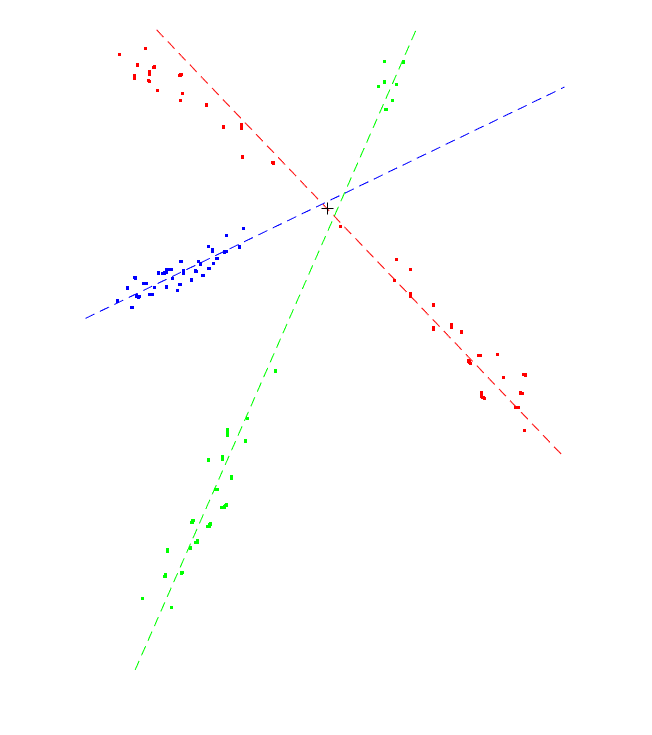

% code here
norm_red_l = red_l./(red_l(3));
norm_green_l = green_l./(green_l(3));
norm_blue_l = blue_l./(blue_l(3));
A = [red_l';green_l';blue_l'];
[~,~,V] = svd(A);
intersect=V(:,end);
norm_intersect = intersect./(intersect(3));
figure
him=imshow(dots);
hold on;
line(xCoords,red_yCoords,'LineStyle','--','Color','r')
line(xCoords,green_yCoords,'LineStyle','--','Color','g')
line(xCoords,blue_yCoords,'LineStyle','--','Color','b')
hpts=plot(norm_intersect(1),norm_intersect(2),'k+','MarkerSize',7);

# Question 4

## 4 (a)

We use procedure in 3(b). The result is not satisfactory because we have too many outliers. Outliers can have a strong impact on the result because we use least square as our cost function which penalize more on those outliers.

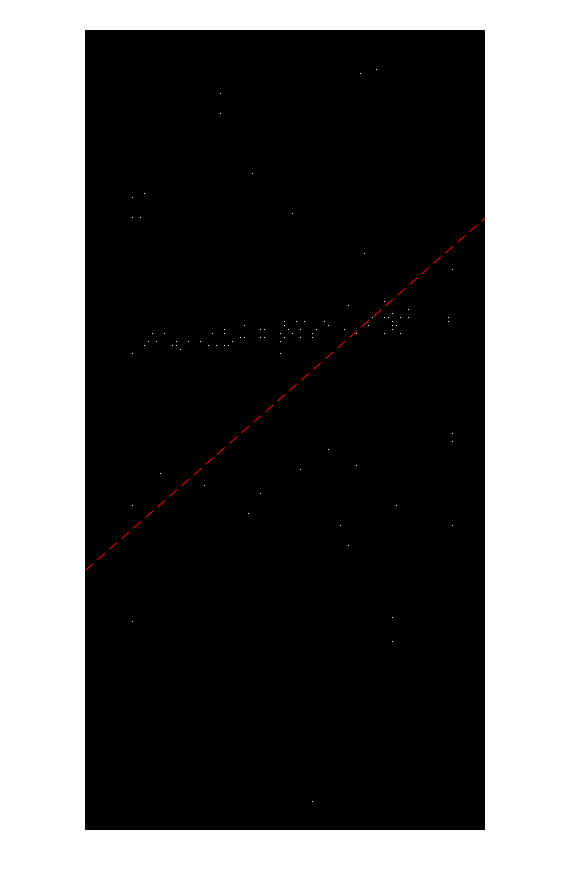

% code here
filename = './data/dots_outliers.tif';
dots_outlier = imread(filename);
shape = size(dots_outlier);
whiteidx = find(dots_outlier == 255);
white_crd = ones(length(whiteidx),3);
[white_crd(:,2),white_crd(:,1)] = ind2sub(shape(1:2),whiteidx); % black coordinates
[~,~,V] = svd(white_crd);
white_l=V(:,end);
white_yCoords = -(repmat(white_l(1),[1,2]).* xCoords + repmat(white_l(3),[1,2]))./ repmat(white_l(2),[1,2]);
figure 
imshow(dots_outlier)
line(xCoords,white_yCoords,'LineStyle','--','Color','r')

## 4 (b)

At each iteration we randomly choose two points from those white points and form a line. We then compute the number of inliers. Finally we plot the line with the most inliers. The result is better than (a).

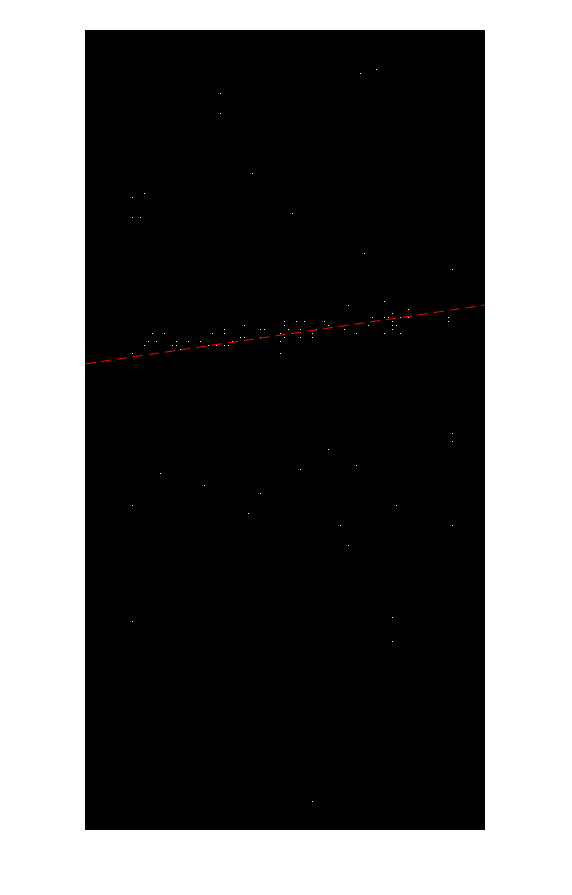

% code here
num_iter = 100; % number of RANSAC iterations
inlier_threshold = 20; % threshold for inlier set of each line
num_inliers = 0;
k_h = 0;
b_h = 0;
for i=1:num_iter
    randidx = randperm(length(whiteidx));
    selected_points = white_crd(randidx(1:2),:);
    k=(selected_points(1,2)-selected_points(2,2))/(selected_points(1,1)-selected_points(2,1));
    b=selected_points(1,2)-k*selected_points(1,1);
    other_points = white_crd(randidx(3:end),:);
    tmp_num_inliers = sum(abs(other_points(:,2)-(k*other_points(:,1)+b))<inlier_threshold);
    if(tmp_num_inliers>num_inliers)
        num_inliers = tmp_num_inliers;
        k_h = k;
        b_h = b;
    end
end
RANSAC_yCoords = k_h*xCoords+b_h;
figure 
imshow(dots_outlier)
line(xCoords,RANSAC_yCoords,'LineStyle','--','Color','r')

# Question 5

First we construct two inhomogeneous vectors$\tilde \mathbf x_{21} =(\tilde \mathbf x_2-\tilde \mathbf x_1) = (m,0)$ and $\tilde \mathbf x_{31} =(\tilde \mathbf x_3-\tilde \mathbf x_1) = (0,m)$. $ \mathbf x_{21} = (m,0,0)$ and $ \mathbf x_{31} = (0,m,0)$

Then we know the area of triangle before transformation is 


$$\frac{| \mathbf x_{21}\times \mathbf x_{31}|}{2} = \frac{||\tilde\mathbf x_{21}||\tilde\mathbf x_{31}|\sin(\theta)\mathbf n|}{2}\mathpunct, \theta = \pi/2 \\
= \frac{||\tilde\mathbf x_{21}||\tilde\mathbf x_{31}||}{2} = \frac{m^2}{2}$$


After affine tranformation


$$\tilde\mathbf x_{21}' = \mathbf H\tilde\mathbf x_{21} = (ma_{11},ma_{21})\\
\tilde\mathbf x_{31}' = \mathbf H\tilde\mathbf x_{31}  = (ma_{12},ma_{22})\\
\mathbf x_{21}' = (ma_{11},ma_{21},0)\\
\mathbf x_{31}' = (ma_{12},ma_{22},0)$$


Then the area of the triangle after transformation is


$$\frac{|\mathbf H\mathbf x_{21}\times \mathbf H\mathbf x_{31}|}{2}\\
= (0,0,m^2(a_{11}a_{22}-a_{12}a_{21}))$$


Thus the area scaled with  $(a_{11}a_{22}-a_{12}a_{21})$, which is exactly $\mathbf {\det}(\mathbf H)$.

If two right triangles (with *m *= *m*1 and *m *= *m*2) are warped by the same affine transformation, the ratio of their areas is preserved because both of their areas are scaled by $\mathbf {\det}(\mathbf H)$ and therefore the ratio maintains the same.